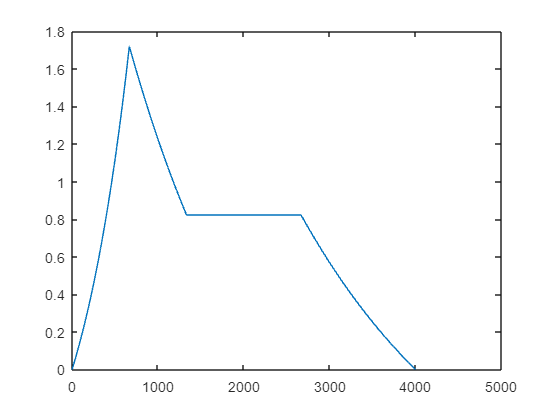

clear
clc

thalf = [0:0.000125:0.25]; % 半拍时间向量
tfull = [0:0.000125:0.5]; % 一拍时间向量
hlent = length(thalf); % 半拍采样点个数
flent = length(tfull); % 一拍采样点个数
t3h = linspace(0,1,ceil(hlent/3)); % 半拍的1/3长度时间向量
t6h = linspace(0,1,ceil(hlent/6)); % 半拍的1/6长度时间向量
envh = [exp(t6h)-1,exp(1-t6h/2.5)-1,(exp(0.6)-1)*ones([1,hlent/3-1]),exp(0.6*(1-t3h))-1]; % 半拍所用包络
t3f = linspace(0,1,ceil(flent/3)); % 一整拍 同理
t6f = linspace(0,1,ceil(flent/6));
envf = [exp(t6f)-1,exp(1-t6f/2.5)-1,(exp(0.6)-1)*ones([1,ceil(flent/3)-1]),exp(0.6*(1-t3f))-1];
plot(envf); % 查看包络形状


%half
Gaph = zeros([1,hlent]).*envh; % Gap空拍
Ch = sin(523.25*2*pi()*thalf).*envh; % 523.25Hz的音
Dh = sin(587.33*2*pi()*thalf).*envh; % 以下类似
Gh = sin(392.25*2*pi()*thalf).*envh;
Fh = sin(349.23*2*pi()*thalf).*envh;
DLh = sin(293.66*2*pi()*thalf).*envh;

%full
Gapf = zeros([1,flent]).*envf;
Cf = sin(523.25*2*pi()*tfull).*envf;
Df = sin(587.33*2*pi()*tfull).*envf;
Gf = sin(392.25*2*pi()*tfull).*envf;
Ff = sin(349.23*2*pi()*tfull).*envf;
DLf = sin(293.66*2*pi()*tfull).*envf;

%sound
sound([Cf,Ch,Dh,Gf,Gapf,Ff,Fh,DLh,Gf,Gapf],8000); % 播放